# WELCOME TO V768 - Measuring Vision with Psychophysics

## Lab 4 - Contrast Sensitivity Functions

In Lab 3, you learned that a **psychometric function** models the relationship between a given stimulus feature (e.g., contrast) and a participant's forced-choice responses and that psychometric functions are ***inferential models***, meaning that they allow you to infer certain things about the relationship that they model. But what you can infer once you've fit a psychometric function to data? And what if you want to vary two stimulus features?

In this lab, you'll learn about inferring ***threshold*** and ***sensitivity*** from psychometric functions and about how those numbers allow you to analyze performance when two stimulus features vary. You'll use that knowledge to plot your **contrast sensitivity function** (aka modulation transfer function).

### Learning Outcomes

(i.e., what you will be able to do at the end of this lab)

- Describe how threshold and sensitivity are measured from a psychometric curve.

- Explain how forced-choice responses can be analyzed when an experiment involves varying more than one stimulus feature.

- Describe what a contrast sensitivity function is and how to measure one.

### Questions

#### A. Computing threshold and sensitivity from a psychometric curve.

- The example in Part A, shows you how to calculate the threshold and sensitivity for a 2AFC task.  To calculate threshold, you simply find the stimulus value at 75% correct.  How would you calculate the threshold if this was a Yes/No task and performance ranged from 0 to 100 percent?

#### B. Measuring a Contrast sensitivity function

- TODO (Clean this up) Write a figure caption for the visualization of fits, the contrast threshold panel and the contrast sensitivity panel.

#### C. Wrap-Up

- Not sure yet.

## Part A. Making Inferences from Psychometric Functions

In Lab 3, we used the psychometric equation 


$$\mathbf{p}=\psi \left(\mathbf{x};\mu ,\sigma ,\gamma ,\lambda \right)=\mathrm{CDF}\left(\mathbf{x};\mu ,\sigma \right)\cdot \left(1-\gamma -\lambda \right)+\gamma$$


where $\psi$ is the psychometric function, $\mathbf{x}$ is the set of stimulus levels (the input of function $\psi$), $\mathbf{p}$ is the set of response probabilities (the output of function $\psi$), $\mu$ is the mean of the underlying cumulative density function (CDF), $\sigma$ is the standard deviation of that CDF, $\gamma$ is the guess rate, and $\lambda$ is the lapse rate.

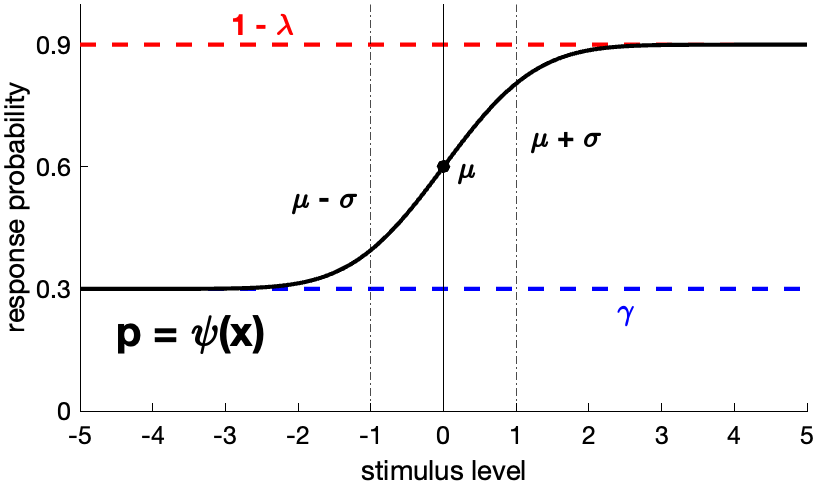

### Step 1. Use the inverse psychometric function

When we put stimulus levels $\mathbf{x}$ into function $\psi$, we get back a set of response probabilties $\mathbf{p}$. What if instead we want to input a response probability and find out the corresponding stimulus level? To do that, we need to ***invert*** our equation. In other words, we need to swap things around to go from our function $\mathbf{p}=\psi \left(\mathbf{x}\right)$ to its **inverse**, function $\mathbf{x}=\psi^{-1} \left(\mathbf{p}\right)$.

To isolate $\mathbf{x}$, we can first use algebra to isolate $\mathrm{CDF}\left(\mathbf{x}\right)$:


$$\mathbf{p}=\mathrm{CDF}\left(\mathbf{x}\right)\cdot \left(1-\gamma -\lambda \right)+\gamma$$



$$\mathbf{p}-\gamma =\textrm{CDF}\left(\mathbf{x}\right)\cdot \left(1-\gamma -\lambda \right)$$



$$\frac{\mathbf{p}-\gamma }{1-\gamma -\lambda }=\mathrm{CDF}\left(\mathbf{x}\right)$$


We can then fully isolate $\mathbf{x}$ using the inverse of the CDF (${\mathrm{CDF}}^{-1}$):


$${\mathrm{CDF}}^{-1} \left(\mathrm{CDF}\left(\mathbf{x}\right)\right)={\mathrm{CDF}}^{-1} \left(\frac{\mathbf{p}-\gamma }{1-\gamma -\lambda }\right)$$



$$\mathbf{x}={\mathrm{CDF}}^{-1} \left(\frac{\mathbf{p}-\gamma }{1-\gamma -\lambda }\right)$$


With the parameters of each function included (noted after a semicolon), this gives us the inverse psychometric equation


$$\mathbf{x}=\psi^{-1} \left(\mathbf{p};\mu ,\sigma ,\gamma ,\lambda \right)={\mathrm{CDF}}^{-1} \left(\frac{\mathbf{p}-\gamma }{1-\gamma -\lambda };\mu ,\sigma \right)$$


Now, we can put a set of response probabilties $\mathbf{p}$ into inverse function $\psi^{-1}$ and get back stimulus levels $\mathbf{x}$.

Let's give that a try with an example psychometric function.

#### Make a demo psychometric curve

Think back to the 2AFC task from Lab 3. Gratings of different contrast levels were shown on either the left or right side of the screen, and you had to choose between left and right, even if you didn't see a stimulus. Because you had two alternatives, you had a 50% chance of being correct just by guessing.

Let's make an example curve for that task and see what it looks like.

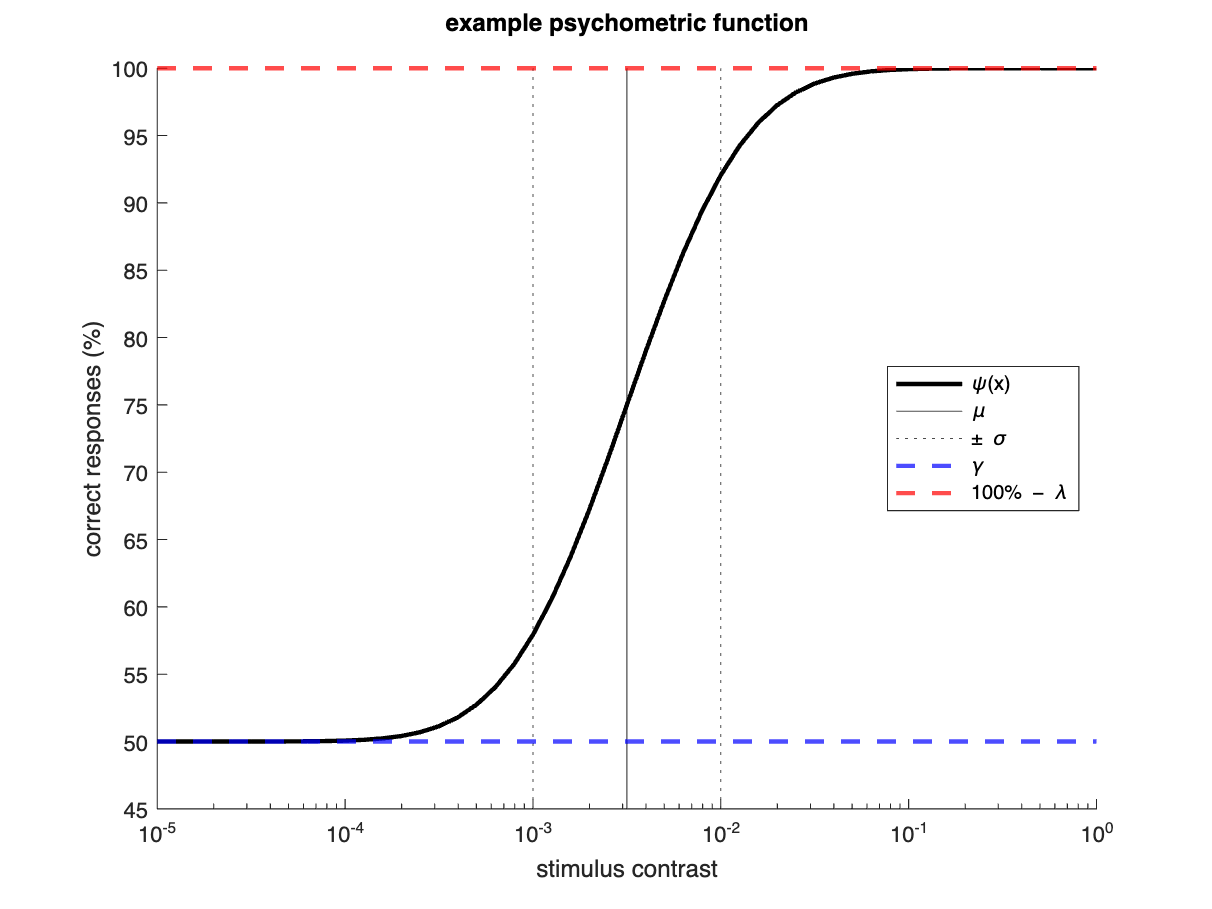

% define psychometric function and its inverse
psyfxn = @(c,x) (normcdf(x, c(1), c(2)) * (1 - c(3) - c(4))) + c(3);
ipsyfxn = @(c,p) norminv((p - c(3))/(1 - c(3) - c(4)), c(1), c(2));
% c(1) = mu
% c(2) = sigma
% c(3) = guess rate
% c(4) = lapse rate

% define example parameters
psy_mu = -2.5;
psy_sig = .5;
psy_lapse = 0;
psy_guess = .5;
psy_params = [psy_mu, psy_sig, psy_guess, psy_lapse];

% create example curve
x_curve = 10.^(-5:.1:0);
y_curve = psyfxn(psy_params, log10(x_curve));

% plot example curve
figure; hold on;
plot(x_curve, y_curve*100, 'k', 'LineWidth',2)
set(gca,'XScale','log')
y_min = 45; ylim([y_min,100])
title(["example psychometric function",""])
xlabel("stimulus contrast")
ylabel("correct responses (%)")

% mark parameter values
xline(10.^psy_mu, 'k-')
xline(10.^(psy_mu+psy_sig), 'k:')
xline(10.^(psy_mu-psy_sig), 'k:')
yline(psy_guess * 100, 'b--', 'LineWidth',2)
yline((1-psy_lapse) * 100, 'r--', 'LineWidth',2)
legend(["\psi(x)", "\mu", "\pm \sigma", "", ...
    "\gamma", "100% "+char(0x2212)+" \lambda"], ...
    'Location','east')

drawnow

This plot shows our example psychometric curve and illustrates our curve's parameters. Recall that $\mu$ and $\sigma$ control the curve's central tendency and spread (x-axis), while $\gamma$ and $\lambda$ control the curve's floor and ceiling (y-axis).

#### Use inverse function to find x given y

Now, let's put a set of response probabilties into the inverse of our example function and see what stimulus levels we get back.

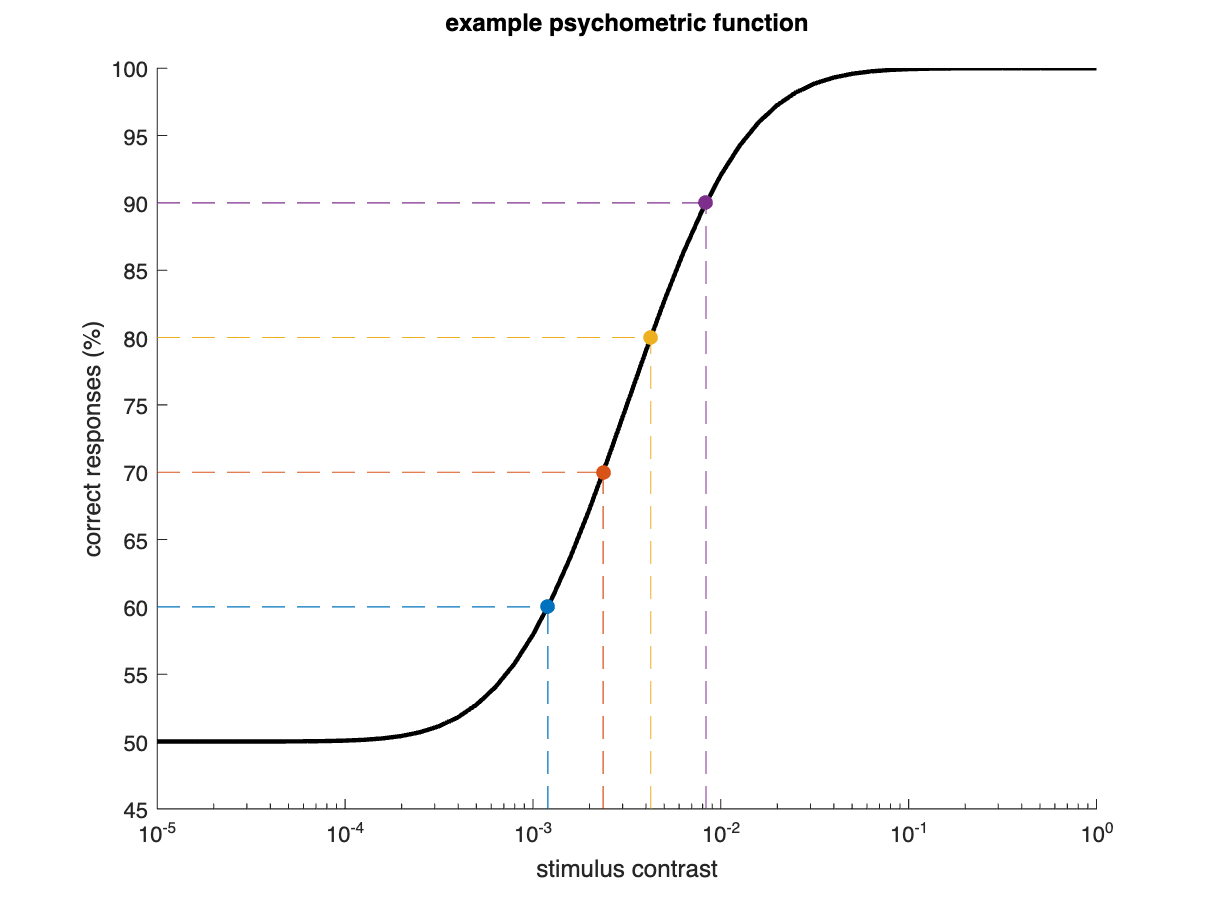

% use response values to find stimulus values
ex_y_vals = (.6:.1:.9).';
ex_log_x = ipsyfxn(psy_params, ex_y_vals);
ex_x_vals = 10.^ex_log_x;

% stash RGB values for default MATLAB colors
% (blue, orange, gold, purple, green, sky blue, red)
rgb_matlab = [0, 0.447, 0.741; 0.85, 0.325, 0.098; 0.929, 0.694, 0.125; ...
    0.494, 0.184, 0.556; 0.466, 0.674, 0.188; 0.301, 0.745, 0.933; 0.635, 0.078, 0.184];

% plot example curve
figure; hold on;
plot(x_curve, y_curve*100, 'k', 'LineWidth',2)
set(gca,'XScale','log')
ylim([y_min,100])
title(["example psychometric function",""])
xlabel("stimulus contrast")
ylabel("correct responses (%)")

% mark calculated values
for i_val=1:length(ex_y_vals)
    this_x = ex_x_vals(i_val); this_y = ex_y_vals(i_val)*100;
    plot([x_curve(1), this_x], [this_y, this_y], ...
        '--', 'Color',rgb_matlab(i_val,:))
    plot([this_x, this_x], [y_min, this_y], ...
        '--', 'Color',rgb_matlab(i_val,:))
    plot(this_x, this_y, ...
        '.', 'Color',rgb_matlab(i_val,:), 'MarkerSize',20);
end

drawnow
disp(table(ex_y_vals, ex_log_x, 'VariableNames',["p","log(x)"]))

     p     log(x) 
    ___    _______

    0.6    -2.9208
    0.7    -2.6267
    0.8    -2.3733
    0.9    -2.0792



**What do you think?** Does it look like our inverse function returned the right stimulus levels?

### Step 2. Measure threshold

Experimenters are often interested in measuring more than one psychometric function, so they try to find ways of summarizing each function with a single number. One common strategy for summarizing psychometric functions is finding the **threshold**.

**What is a threshold?** In psychophysics, a threshold is the stimulus level that forms a ***boundary*** between when the participant can and cannot do the task. That boundary may be clear in some circumstances, but perceptual performance tends to vary ***continuously*** across an experiment's stimulus levels (hence, the typical S-shape of psychometric curves). In other words, there may be a boundary ***line***, but usually, there's more of a boundary ***zone***. Because boundary ***zones*** are more common, the point of finding thresholds is less about the exact numbers you find and more about how the numbers you find ***compare*** to one another.

**How do you calculate threshold? **Typically, an experimenter finds a threshold value by choosing a specific response probability and calculating the stimulus level associated with that response probabiliy. Choosing a response probability is usually a somewhat arbitrary decision, but a common choice is 0.75 (75%).

#### Find the threshold of demo psychometric curve

Let's find the threshold value of the example psychometric function we defined above.

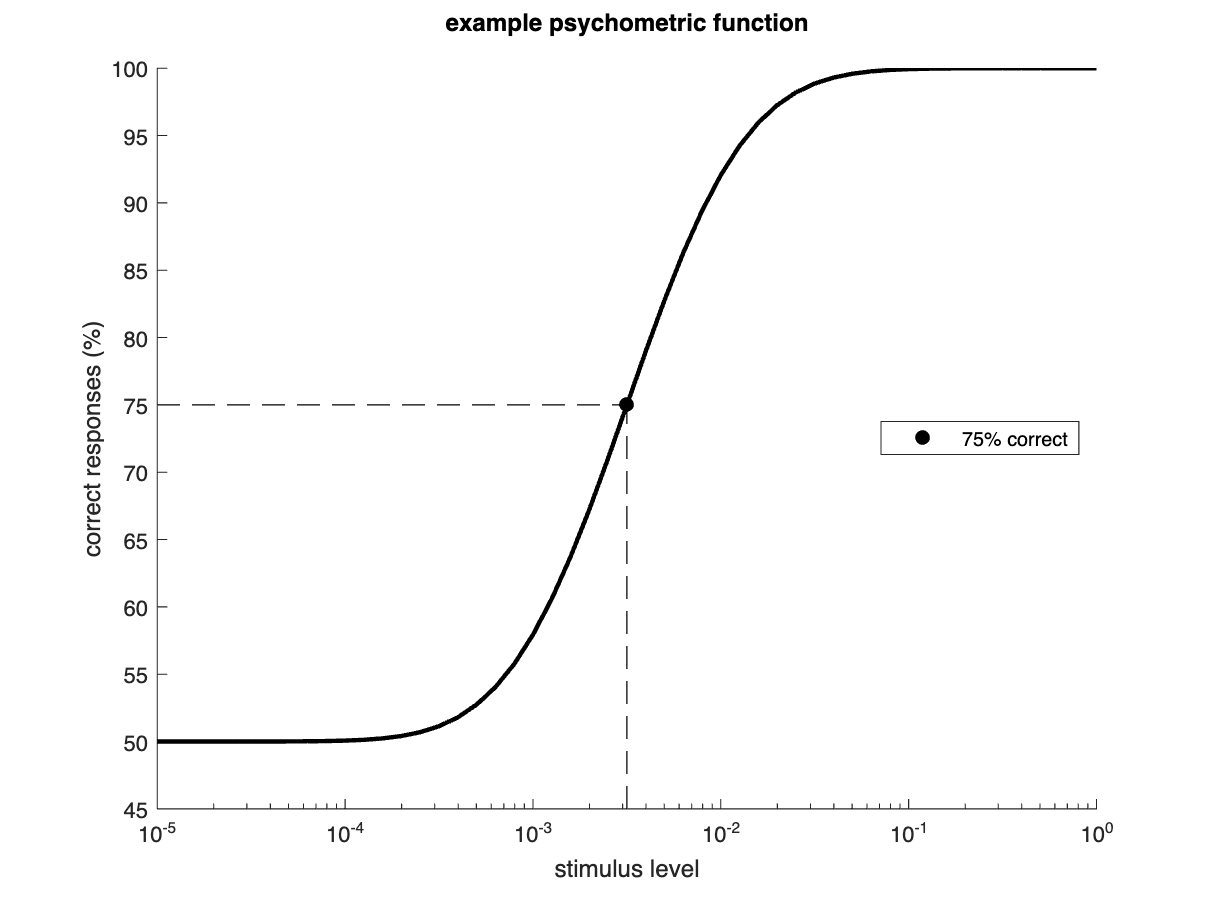

% compute the 75% mark for this psychometric curve
thresh_level = 75;
threshold = 10.^(ipsyfxn(psy_params, thresh_level/100));

% plot the example psychometric function
figure; hold on;
plot(x_curve, y_curve*100, 'k', 'LineWidth',2)
set(gca,'XScale','log')
ylim([45,100])
title(["example psychometric function",""])
xlabel('stimulus level')
ylabel('correct responses (%)')

% add the 75% mark
plot([x_curve(1), threshold], [thresh_level, thresh_level], 'k--')
plot([threshold, threshold], [45, thresh_level], 'k--')
dot_handle = plot(threshold, thresh_level, 'k.', 'MarkerSize',20);
legend(dot_handle, {[num2str(thresh_level) '% correct']}, ...
    'Location','east')

drawnow

For our example curve, the 75% threshold is

fprintf("10^%g \n",log10(threshold))

10^-2.5 


#### Find the threshold of a "better" curve

What if we had chosen a lower $\mu$? An observer with a lower $\mu$ would be ***better*** at detecting low contrast stimuli, so will lowering $\mu$ **increase** or **decrease** the threshold value?

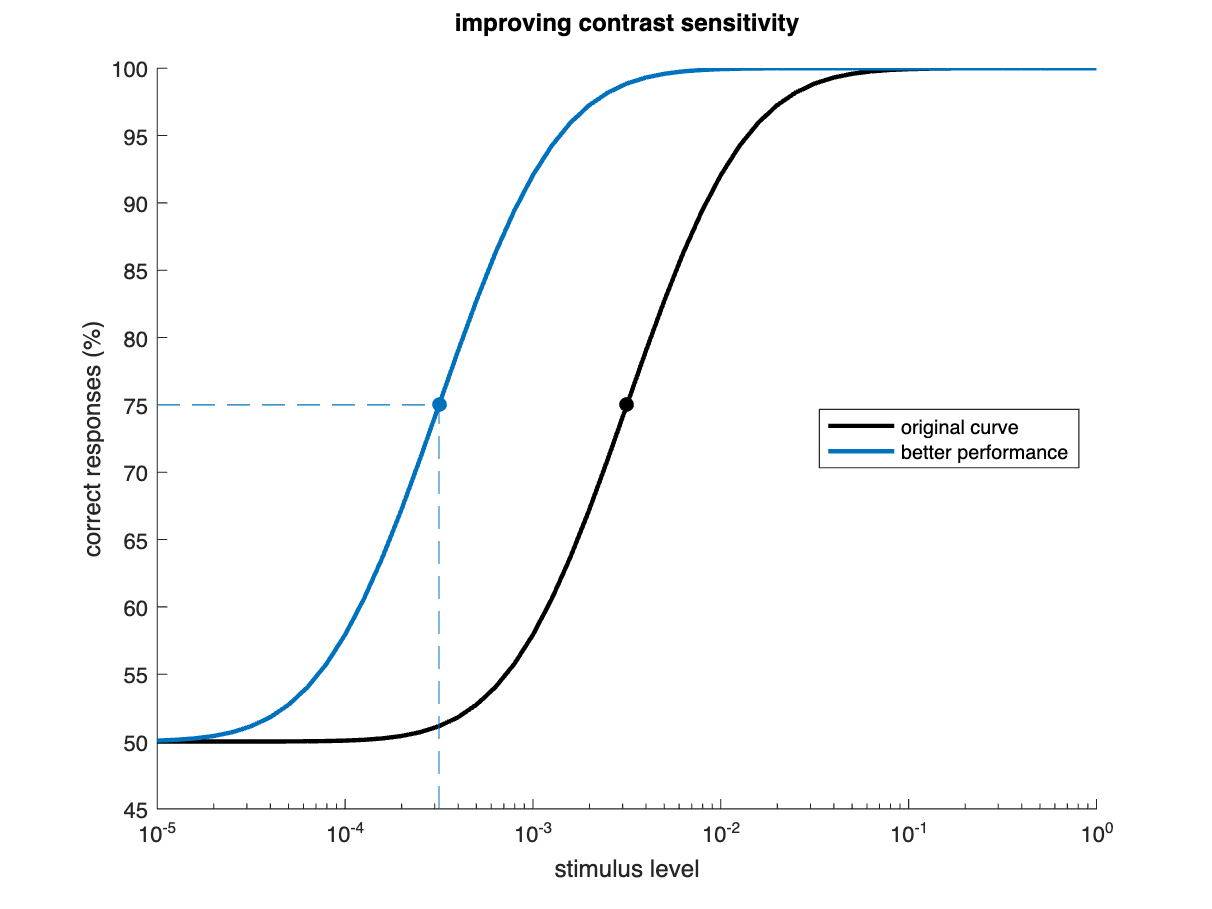

% build a curve with a lower mu
better_mu = psy_mu - 1;
better_params = [better_mu, psy_sig, psy_guess, psy_lapse];
better_curve = psyfxn(better_params, log10(x_curve));

% compute the 75% mark for this psychometric curve
better_threshold = 10.^(ipsyfxn(better_params, thresh_level/100));

% plot the original example psychometric function
figure; hold on;
plot(x_curve, y_curve*100, 'k', 'LineWidth',2)
plot(threshold, thresh_level, 'k.', 'MarkerSize',20)
set(gca,'XScale','log')
ylim([45,100])
xlabel('stimulus level')
ylabel('correct responses (%)')

% plot the better curve
plot(x_curve, better_curve*100, ...
    'LineWidth',2, 'Color',rgb_matlab(1,:))
plot([x_curve(1), better_threshold], [thresh_level, thresh_level], ...
    '--', 'Color',rgb_matlab(1,:))
plot([better_threshold, better_threshold], [45, thresh_level], ...
    '--', 'Color',rgb_matlab(1,:))
plot(better_threshold, thresh_level, ...
    '.', 'MarkerSize',20, 'Color',rgb_matlab(1,:))
title(["improving contrast sensitivity",""])
legend(["original curve","","better performance"], ...
    'Location','east')

drawnow

For our new and improved curve, the 75% threshold is

fprintf("10^%g \n",log10(better_threshold))

10^-3.5 


So, will a **"better" observer** (one with a lower $\mu$) have a **higher** or **lower** threshold value?

if better_threshold > threshold
    disp("higher")
elseif better_threshold < threshold
    disp("lower")
else
    disp("equal")
end

lower


We usually associate higher values with better performance, so this may seem counterintuitive unless you step through the logic. If you could only see a few of the gratings in Lab 3's 2AFC task, your threshold would fall among the highest contrast levels displayed. If you could see almost all of the gratings, your threshold would fall among the lowest contrast levels displayed. Thus, when performance on the task is worse, thresholds will be larger, and when performance on the task is better, thresholds will be smaller.

Imagine varying a second stimulus feature like spatial frequency. Thresholds will be small for spatial frequencies you can see easily, and thresholds will be large for spatial frequencies you have trouble seeing. If you plot spatial frequency on the x-axis and threshold on the y-axis, higher y-values will indicate worse performance. Because higher y-values usually indicate better performance, a glance at the plot will generally give the wrong impression. As a result, psychophysicists usually plot **sensitivity** instead of (or in addition to) threshold.

### Step 3. Measure sensitivity

**What is sensitivity?** Sensitivity quantifies how easily you can sense a stimulus. If you could only see a few of the gratings in Lab 3's 2AFC task, your contrast sensitivity would be low. If you could see almost all of the gratings, your contrast sensitivity would be high.

Thresholds are often converted into sensitivities by simply taking the reciprocal of the threshold:


$$\mathrm{sensitivity}=\frac{1}{\mathrm{threshold}}$$


#### Find the sensitivity of demo psychometric curve

The sensitivity of our original example curve is

disp(1/threshold)

  316.2278



#### Find the threshold of a "better" curve

Meanwhile, the sensitivity of our new and improved curve is

disp(1/better_threshold)

   3.1623e+03



which is

if (1/better_threshold) > (1/threshold)
    disp("higher")
elseif (1/better_threshold) < (1/threshold)
    disp("lower")
else
    disp("equal")
end

higher


Thus, when performance on the task is worse, sensitivity will be lower, and when performance on the task is better, sensitivity will be higher.

Again imagine varying a second stimulus feature like spatial frequency. Sensitivity will be high for spatial frequencies you can see easily, and sensitivity will be low for spatial frequencies you have trouble seeing. In a resulting plot with spatial frequency on the x-axis and sensitivity on the y-axis, higher y-values will indicate better performance, as one would generally expect. As a result, that plot should be more easy to interpret, even with only a glance.

## Part B. Measure a contrast sensitivity function

### Step 1. Data collection

To collect data, open the PsychoPy ".psyexp" file in the folder titled "contrast-sensitivity", and run that experiment. The instructions will appear on the screen before the trials begin. The experiment includes XXX trials measuring contrast sensitivity at 5 spatial frequencies (1cpd, 2cpd, 4cpd, 8cpd, 16cpd).

### Step 2. Load your data

Before running this section of code, find the name of the ".csv" file containing your experiment data, and enter it below.

file_location = 'contrast-sensitivity/data/';
id = 'demo2';

psycho_data = table;
files = dir([file_location, id,'*.csv'])

files = 3×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


warning off;
for ff = 1:length(files)
    fprintf('loading %s ...\n',files(ff).name)
    tmp=readtable([files(ff).folder,'/',files(ff).name]);
    psycho_data = [psycho_data; tmp];
end

loading demo2_contrast_sensitivity_2025-01-26_16h15.23.030.csv ...
loading demo2_contrast_sensitivity_2025-01-26_16h34.42.314.csv ...
loading demo2_contrast_sensitivity_2025-01-26_16h43.44.651.csv ...


warning on;

% remove the rows/columns associated with the instructions in psychopy
psycho_data(1,:)=[];
remove = {'notes','begin_experiment_started','begin_experiment_stopped'};
psycho_data(:,remove) = [];

### Step 3. Visualize your performance

For this experiment, the target stimulus was a grating with a contrast of *e* to the power of -1 (approx. 0.37). The participant controlled the contrast of a second grating and pressed a button when the contrast of the two gratings seemed to match. PsychoPy saved the contrast of the controlled grating at the time of response, as well as the initial contrast level of that grating (either high or low).

**Re-organize the psychopy data into a new table for analysis.**

% set some measurements that we'll use to calculate approximate values for the spatial frequencies
viewing_distance = 60; % cm  -- This should be about right for sitting at a desk and looking at a laptop
screen_height = 20; %cm -- For Kate's macbook pro 15 inch
cm2deg = (2*atan2d(screen_height/2,viewing_distance))/screen_height;

% re-organize the psychopy data into a new table for analysis
analyze = table;
analyze.contrast = psycho_data.contrast;
contrast_levels = unique(analyze.contrast);
grating_location = psycho_data.location;
response_location = psycho_data.response_keys;
analyze.correct = (grating_location==1 & strcmp(response_location,'right')) | (grating_location==-1 & strcmp(response_location,'left'));

% calculate the spatial frequency (keep in mind that this is fairly
% approximate)
analyze.sf = 1./(psycho_data.size./2*screen_height*cm2deg);


**Group the data by spatial frequency and contrast**

g = grpstats(analyze,{'contrast','sf'})

g = 30×4 table
                       contrast      sf       GroupCount    mean_correct
                       ________    _______    __________    ____________

    1e-08_0.264206       1e-08     0.26421        36          0.55556   
    1e-08_0.528412       1e-08     0.52841        36          0.47222   
    1e-08_1.05682        1e-08      1.0568        36          0.47222   
    1e-08_2.11365        1e-08      2.1136        36          0.44444   
    1e-08_4.22729        1e-08      4.2273        36          0.44444   
    0.0001_0.264206     0.0001     0.26421        36          0.83333   
    0.0001_0.528412     0.0001     0.52841        36             0.75   
    0.0001_1.05682      0.0001      1.0568        36   

frequencies = unique(g.sf);
g.percent_correct = 100*g.mean_correct;


**Visualize the percent correct per condition (per spatial frequency and contrast)**

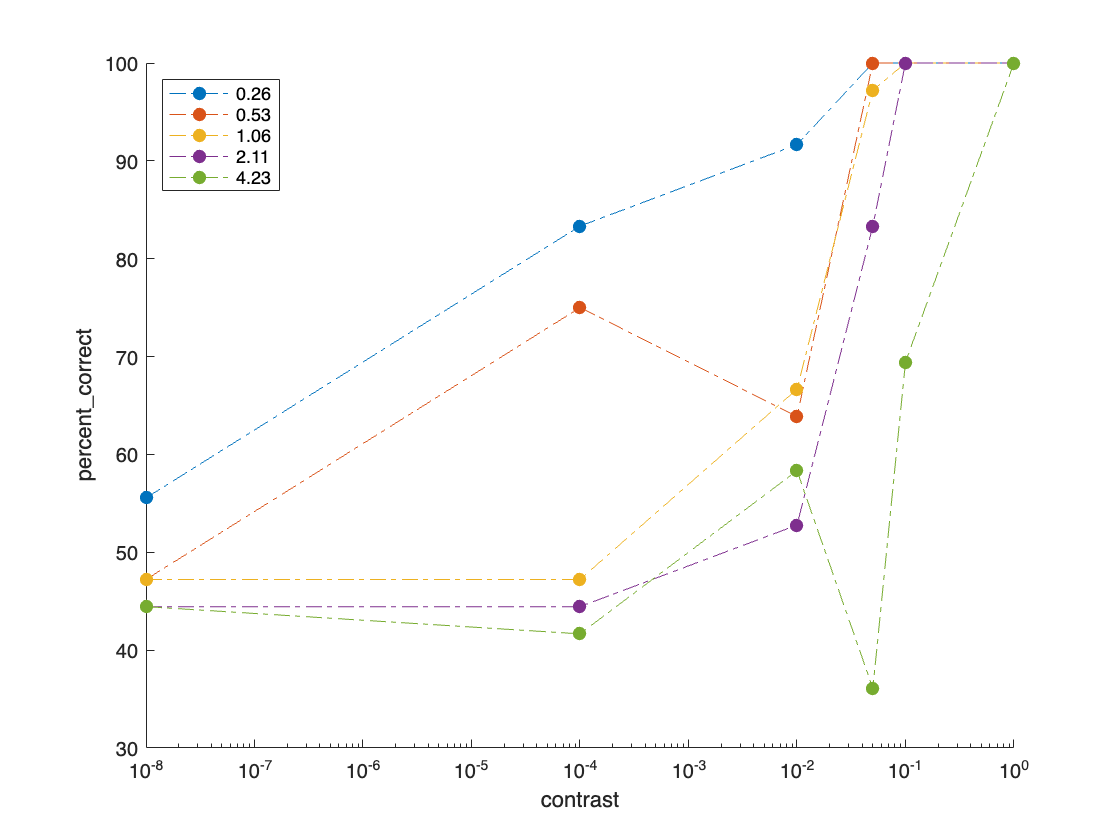

figure(); clf; hold on;
for ff=1:length(frequencies)
    data_lines(ff) = plot(g(g.sf==frequencies(ff),:),"contrast","percent_correct",'LineStyle','-.','marker','.','markersize',20);
end
set(gca,'XScale','log')
legend(num2str(frequencies,'%.2f'),'Location','northwest')
title('')

drawnow;

### Step 4. Fit psychometric curves and compute threshold/sensitivity

In order to calculate the threshold, we need to fit psychometric curves to the data for each spatial frequency and then calculate the threshold (contrast value at 75%).

#### **Fit psychometric curves to the data.**

% TODO grab this from Lab 3

#### **Visualize fits. **

% TODO 

#### **Compute/Visualize threshold.**

% TODO 

#### **Compute/Visualize sensitivity.**

% TODO 

# **Text drafts**

**[Temporary holding cell. TODO: Remove after finishing full draft.]**

One of the things that we can infer from a psychometric function is a participant's **threshold**.

Think back to the 2AFC task from Lab 3. You were forced to choose between left and right. If you guessed, you had a 50% chance of being correct. Thus, chance performance for that task (and similar tasks) is 50%.

Recall that a psychometric function is an ***inferential model***. Therefore, we can infer certain things from a psychometric function about the relationship between a given stimulus feature (e.g., contrast) and a participant's forced-choice responses. One of those things is a participant's **threshold**. For 2AFC tasks like the one from Lab 3, the threshold is typically defined as the stimulus level associated with a response probability of 75%, halfway between chance (50%) and perfect (100%) performance.

Thresholds will be small for spatial frequencies you can see easily, and thresholds will be large for spatial frequencies you have trouble seeing.  This means that when thresholds are small, performance on the task will be better.  And when thresholds are large, performance the task is worse.  Generally this can make interpreting thresholds on a graph difficult -- it is somewhat more intuitive for numbers to go up with good performance and down with bad performance.  As a result, thresholds are often converted into sensitivities by simply taking the reciprocal of threshold.